## Exam 10 June 2014

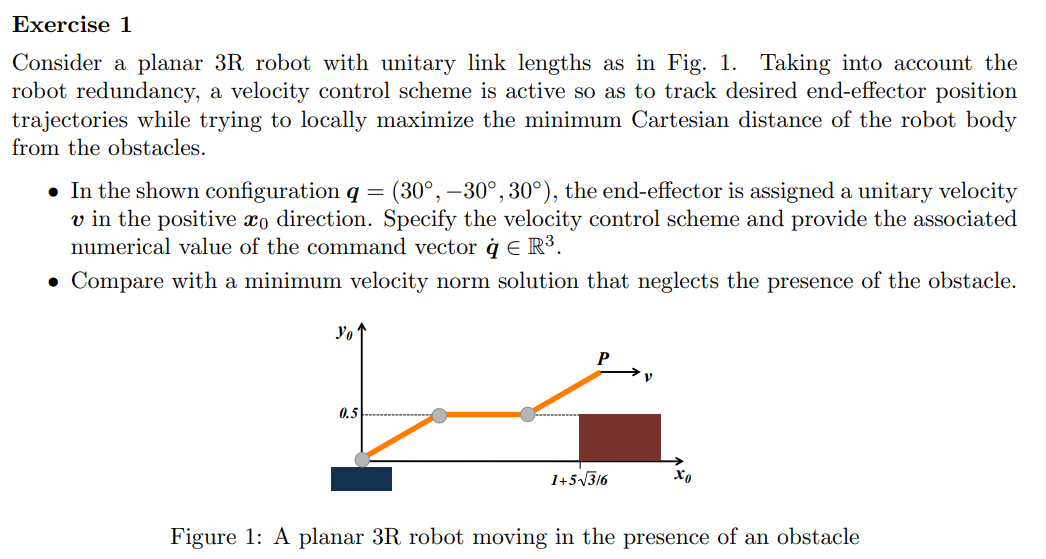

syms q1 q2 q3 q_dot_1 q_dot_2 q_dot_3 m n real
syms l m1 m2 m3 real

p = [cos(q1)+cos(q1+q2)+cos(q1+q2+q3);
     sin(q1)+sin(q1+q2)+sin(q1+q2+q3);]

$$p = \left(\begin{array}{c} \cos\left(q_{1}+q_{2}+q_{3}\right)+\cos\left(q_{1}+q_{2}\right)+\cos\left(q_{1}\right)\\ \sin\left(q_{1}+q_{2}+q_{3}\right)+\sin\left(q_{1}+q_{2}\right)+\sin\left(q_{1}\right) \end{array}\right)$$

J = jacobian(p,[q1,q2,q3]);

v = [1;0;];

J_subs = eval(subs(J,[q1,q2,q3],[pi/6,-pi/6,pi/6]));

% Minimum norm solution for Task 1
q_dot = pinv(J_subs(1,:))*v(1);
disp("Minimum norm solution for Task 1:");

Minimum norm solution for Task 1:


disp(q_dot);

   -0.6667
   -0.3333
   -0.3333




a = find_near_pos();

Position of CoM 1: 
    0.4330
    0.4330

Position of CoM 2: 
    1.3660
    0.5000

Position of CoM 3: 
    2.2990
    0.7500

Position of  P1: 
    0.8660
    0.8660

Position of CoM P2: 
    1.8660
    0.5000

Position of CoM P3: 
    2.7321
    1.3660



pt =     0.4330
    0.4330


d2 = 3.4544

pt =     1.3660
    0.5000


d2 = 2.5207

pt =     2.2990
    0.7500


d2 = 1.6073

pt =     0.8660
    0.8660


d2 = 3.0428

pt =     1.8660
    0.5000


d2 = 2.0207

pt =     2.7321
    1.3660


d2 = 1.4434


>>> Punto più vicino trovato:
Distanza minima^2: 1.443376
Punto più vicino: (2.7321, 1.3660)



d = [1+(5*sqrt(3))/6 0.5];
c3_x = cos(q1)+cos(q1+q2)+0.5*cos(q1+q2+q3);
c3_y = sin(q1)+sin(q1+q2)+0.5*sin(q1+q2+q3);
point = [c3_x c3_y];
H= norm(point-d)^2;
grad_H=jacobian(H,[q1,q2,q3]);
grad_H_subs = eval(subs(grad_H,[q1,q2,q3],[pi/6,-pi/6,pi/6]));

J_pinv = pinv(J_subs(1,:));
pro = J_pinv*J_subs(1,:);
d_dot_pg = J_pinv*v(1)+(eye(3)-J_pinv*J_subs(1,:))*grad_H_subs.'

d_dot_pg =    -0.5704
   -0.1796
   -0.6796




function H = find_near_pos()

    q1 = pi/6;
    q2 = -pi/6;
    q3 = pi/6;
    l = 1;
    d = [1+(5*sqrt(3))/3;0.5;];

    c1_x = (l/2)*cos(q1);
    c1_y = (l/2)*cos(q1);
    c1 = [c1_x; c1_y];
    c2_x = cos(q1)+(l/2)*cos(q1+q2);
    c2_y = sin(q1)+(l/2)*sin(q1+q2);
    c2 = [c2_x; c2_y];
    c3_x = cos(q1)+cos(q1+q2)+(l/2)*cos(q1+q2+q3);
    c3_y = sin(q1)+sin(q1+q2)+(l/2)*sin(q1+q2+q3);
    c3 = [c3_x; c3_y];
    
    disp("Position of CoM 1: ");
    disp([c1_x;c1_y;]);
    disp("Position of CoM 2: ");
    disp([c2_x;c2_y;]);
    disp("Position of CoM 3: ");
    disp([c3_x;c3_y;]);

    p1_x = cos(q1);
    p1_y = cos(q1);
    p1 = [p1_x; p1_y];
    p2_x = cos(q1)+cos(q1+q2);
    p2_y = sin(q1)+sin(q1+q2);
    p2 = [p2_x; p2_y];
    p3_x = cos(q1)+cos(q1+q2)+cos(q1+q2+q3);
    p3_y = sin(q1)+sin(q1+q2)+cos(q1+q2+q3);
    p3 = [p3_x; p3_y];

    disp("Position of  P1: ");
    disp([p1_x;p1_y;]);
    disp("Position of CoM P2: ");
    disp([p2_x;p2_y;]);
    disp("Position of CoM P3: ");
    disp([p3_x;p3_y;]);

    candidates = [c1,c2,c3,p1,p2,p3];

    % Ricerca del punto più vicino a d
    min_dist2 = inf;
    closest_point = [0; 0];

    for i = 1:size(candidates, 2)
        pt = candidates(:, i)
        d2 = norm(d-pt)
        if d2 < min_dist2
            min_dist2 = d2;
            closest_point = pt;
        end
    end

    fprintf('\n>>> Punto più vicino trovato:\n');
    fprintf('Distanza minima^2: %.6f\n', min_dist2);
    fprintf('Punto più vicino: (%.4f, %.4f)\n\n', closest_point(1), closest_point(2));
    H = closest_point;
end

    